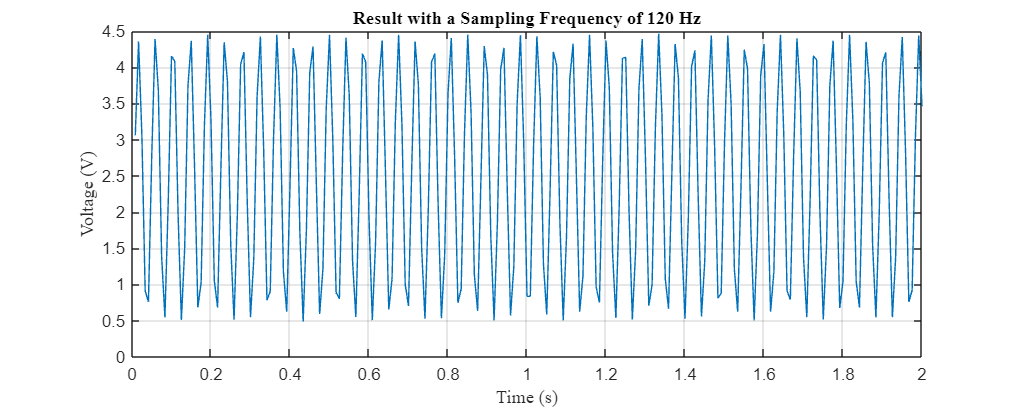

clc, clear


fs = 120;  % Change this only

SamplingTime = 2;
N = SamplingTime * fs;

% --- Load data ---
dataVarName = sprintf("Lab4_Ass1_fs%d", fs);  % Variable name in .mat file
fileName = sprintf("Lab4_Ass1_fs%d.mat", fs);  % File name
load(fileName);  % loads variable with name Lab4_Ass1_fsXX
rawData = eval(dataVarName);  % Extract that variable dynamically

% --- Time vector and scaling ---
t = 1/fs:1/fs:SamplingTime;
y = rawData / 1024 * 5;
tt = 0:0.001:2;
syms t_sym s
R = 33;
C = 1e-4;
G1 = 1/(1+R*C*s);
y_sym = 2.5 * sin(2*pi*23*t_sym) + 2.5;
G2 = laplace(y_sym);
out(t_sym) = ilaplace(G1*G2,t_sym);
yy = out(tt);

% --- Plot 1: Raw Sample Plot ---
fig1 = figure('Name', sprintf("fs = %d Hz", fs));
plot(t, y)
title(sprintf("Result with a Sampling Frequency of %d Hz", fs), 'FontName', 'Times New Roman');
xlabel("Time (s)", 'FontName', 'Times New Roman');
ylabel("Voltage (V)", 'FontName', 'Times New Roman');
grid on
set(fig1, 'Units', 'Inches', 'Position', [0, 0, 10, 4], 'PaperPositionMode', 'auto');

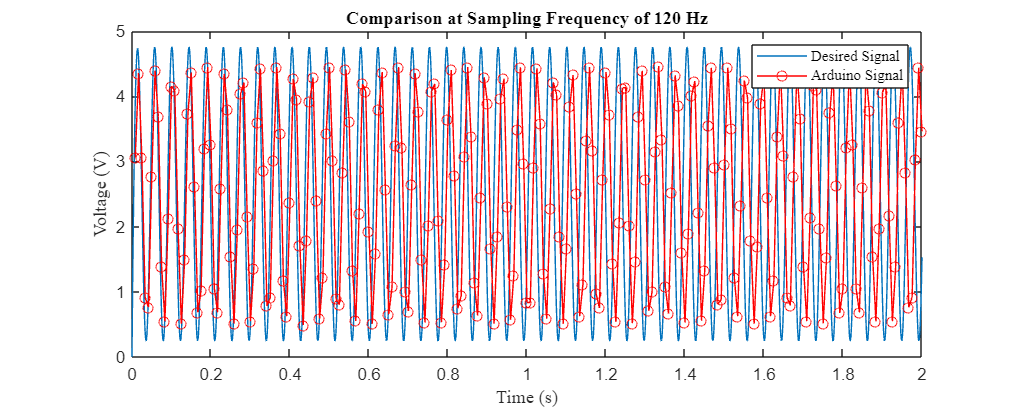

% exportgraphics(fig1, sprintf('f%d.png', fs), 'Resolution', 600);

% --- Plot 2: Compare with Desired Signal ---
fig2 = figure();
plot(tt, yy);
hold on;
plot(t, y, '-o', 'Color', 'red');
title(sprintf("Comparison at Sampling Frequency of %d Hz", fs), 'FontName', 'Times New Roman');
xlabel("Time (s)", 'FontName', 'Times New Roman');
ylabel("Voltage (V)", 'FontName', 'Times New Roman');
legend("Desired Signal", "Arduino Signal", 'FontName', 'Times New Roman');
hold off;
set(fig2, 'Units', 'Inches', 'Position', [0, 0, 10, 4], 'PaperPositionMode', 'auto');
exportgraphics(fig2, sprintf('f%d_compare.png', fs), 'Resolution', 600);


% --- Plot 3: FFT Analysis ---
hann_win = hann(N);
Y = fft((y - 2.5) .* hann_win);
P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(N/2))/N;

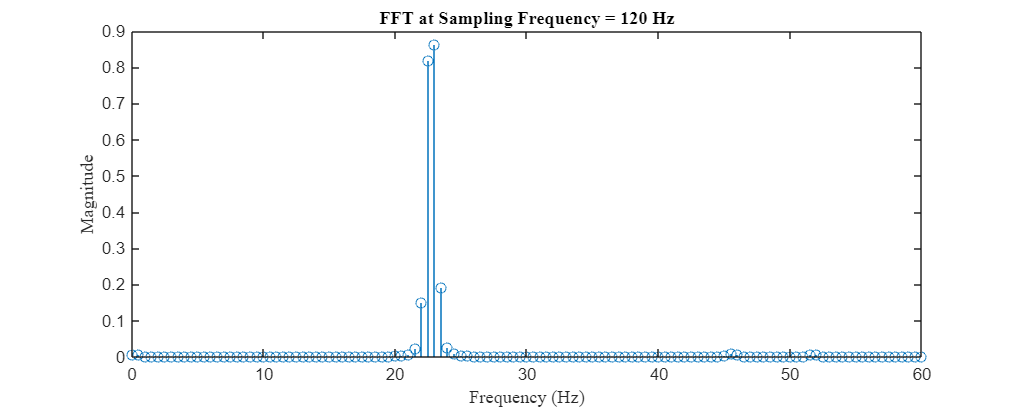


fig3 = figure();
stem(f, P1');
title(sprintf("FFT at Sampling Frequency = %d Hz", fs), 'FontName', 'Times New Roman');
xlabel("Frequency (Hz)", 'FontName', 'Times New Roman');
ylabel("Magnitude", 'FontName', 'Times New Roman');
set(fig3, 'Units', 'Inches', 'Position', [0, 0, 10, 4], 'PaperPositionMode', 'auto');
exportgraphics(fig3, sprintf('f%d_fft.png', fs), 'Resolution', 600);